% Author: Kenneth H.L. Ho
% Copyright 2019 RIKEN BDR
% License: GPL v3 https://www.gnu.org/licenses/gpl-3.0.txt 

# Basic Image Processing 

## Download C.elegnas embryo (Kyoda et al., 2013), Image id=1, Z=30, t=0, from SSBD database

## Reading an image from file

url_image = "http://ssbd.qbic.riken.jp/image/webgateway/render_image/1/30/0"

url_image = "http://ssbd.qbic.riken.jp/image/webgateway/render_image/1/30/0"

k_img1 = imread(url_image)

k_img1 = 600×600×3 uint8 array
k_img1(:,:,1) =

    31    31    31    32    32    32    33    33    31    30    30    30    32    33    32    31    29    30    31    32    32    32    32    32    31    31    31    31    31    31    31    31    32    31    30    30    30    31    32    33    32    32    32    31    31    31    30    30    32    31    31    30    30    31    31    32    30    30    30    30    31    31    31    31    31    31    31    32    32    31    31    31    32    32    32    32    32    32    32    32    30    30    30    30    30    30    30    30    34    34    33    33    32    31    31    30    33    30    29    30    33    34    31    28    32    32    32    32    31    31    30    29    31    31    31    32    32    32    33    33    30    31    31    31    32    33    33    33    30    31    31    32    32    32    31    31    32    32    32    31    32    33    34    34    32    32    32    32    32    32    32    32    33    33    33    33    33    33    

imwrite(k_img1, 'k_image.tif', 'tif')

imfinfo('k_image.tif')

ans = struct with fields:
                     Filename: '/MATLAB Drive/k_image.tif'
                  FileModDate: '13-Aug-2019 03:23:49'
                     FileSize: 410726
                       Format: 'tif'
                FormatVersion: []
                        Width: 600
                       Height: 600
                     BitDepth: 24
                    ColorType: 'truecolor'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: [8 8 8]
                  Compression: 'PackBits'
    PhotometricInterpretation: 'RGB'
                 StripOffsets: [1×67 double]
              SamplesPerPixel: 3
                 RowsPerStrip: 9
              StripByteCounts: [1×67 double]
                  XResolution: 72
                  YResolution: 72
               ResolutionUnit: 'Inch'
                     Colormap: []
          PlanarConfiguration: 'Chunky'
                    TileWid

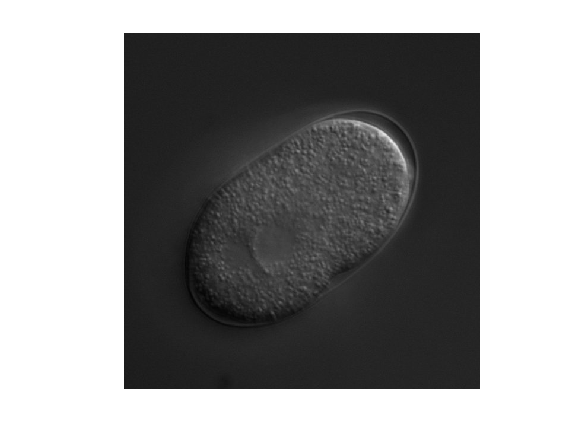

imshow('k_image.tif')

k_img1

k_img1 = 600×600×3 uint8 array
k_img1(:,:,1) =

    31    31    31    32    32    32    33    33    31    30    30    30    32    33    32    31    29    30    31    32    32    32    32    32    31    31    31    31    31    31    31    31    32    31    30    30    30    31    32    33    32    32    32    31    31    31    30    30    32    31    31    30    30    31    31    32    30    30    30    30    31    31    31    31    31    31    31    32    32    31    31    31    32    32    32    32    32    32    32    32    30    30    30    30    30    30    30    30    34    34    33    33    32    31    31    30    33    30    29    30    33    34    31    28    32    32    32    32    31    31    30    29    31    31    31    32    32    32    33    33    30    31    31    31    32    33    33    33    30    31    31    32    32    32    31    31    32    32    32    31    32    33    34    34    32    32    32    32    32    32    32    32    33    33    33    33    33    33    

size(k_img1)

ans =    600   600     3


whos k_img1

  Name          Size                 Bytes  Class    Attributes

  k_img1      600x600x3            1080000  uint8              



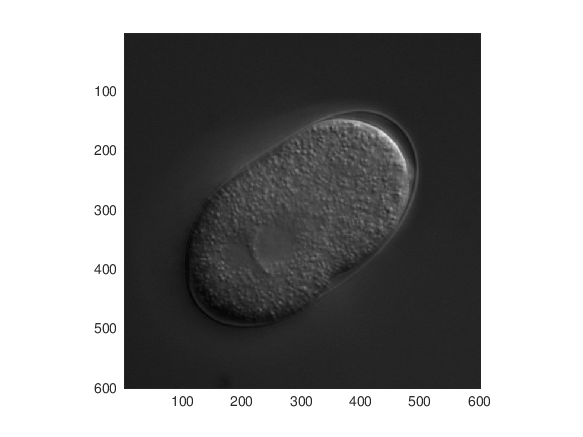

figure;
image(k_img1)
daspect([1,1,1])

% Finding the minumum intensity on Red channel (or whichever as they are of
% the same value)
minvalue = min(min(k_img1(:,:,1)));
disp(minvalue)

   2



% Find the row and column of the image with the minimum intensity value.
[row, col] = find(k_img1(:,:,1)==minvalue);
disp([row, col])

   437   112
   464   158



k_img1(435:439, 110:114,1)

ans = 5×5 uint8 matrix
    7    6    7   19   25
    8    5    4   15   22
   10    5    2   11   19
   13    7    3    7   16
   15    9    4    5   14


maxvalue = max(max(k_img1(:,:,1)))

maxvalue = uint8
238

disp(maxvalue)

   238



[row, col] = find(k_img1(:,:,1)==maxvalue);
disp([row, col])

   182   450
   182   451



k_img1(180:185,450:455,1)

ans = 6×6 uint8 matrix
   213   190   154   122    99    92
   231   220   192   153   121    96
   238   238   221   186   152   113
   231   235   232   213   189   143
   220   223   232   227   215   170
   190   204   214   224   224   202


size(k_img1)

ans =    600   600     3


size(k_img1(1,:,1))

ans =      1   600


rowsize = size(k_img1, 1)

rowsize = 600

colsize = size(k_img1, 2)

colsize = 600

k_img1(rowsize/2, colsize/2, 1)

ans = uint8
64

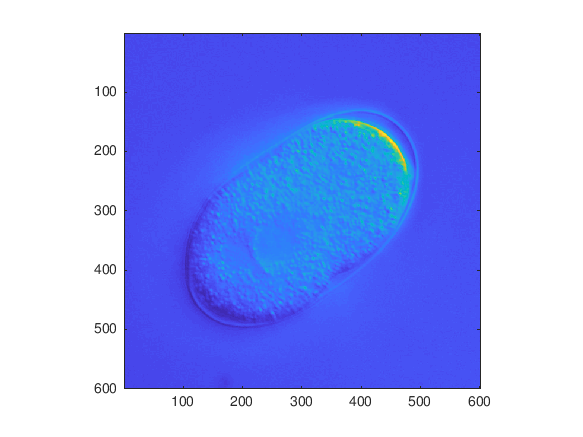

% converting rgb to indexed image
k_img2=rgb2gray(k_img1);

% image scaled colour function; using default colour map
imagesc(k_img2)
daspect([1,1,1])

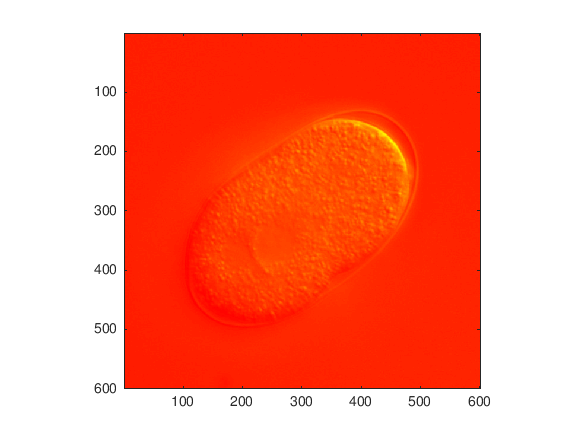

% using autumn colourmap
colormap("autumn");

imagesc(k_img2);
daspect([1,1,1])

% Thresholding
% display all the pixels that are larger than intensity 64
bw = k_img1 > 64;

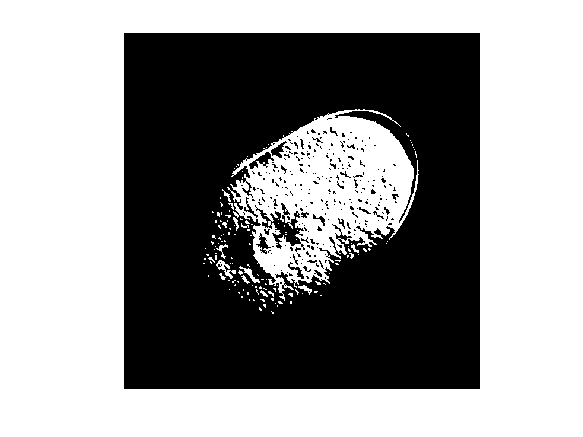

imshow(bw(:,:,1))

% thresholding at 128
bw = k_img1 > 128;

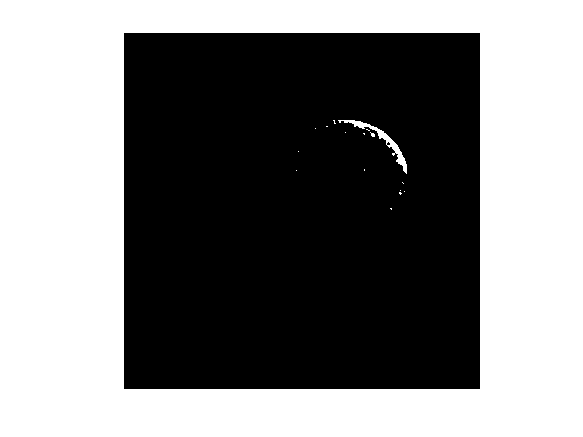

imshow(bw(:,:,1))

% Thresholding at 64
bw2 = k_img2 > 64;
daspect([1,1,1])

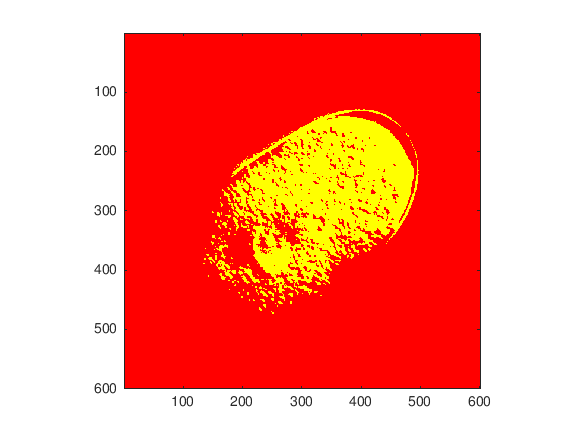

imagesc(bw2)
daspect([1,1,1])

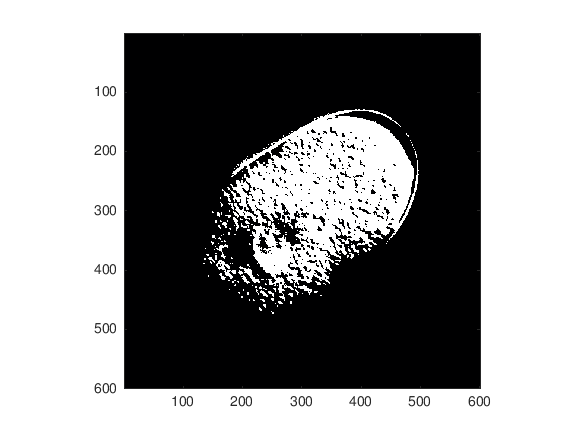

colormap(bone)
daspect([1,1,1])

% filter using average on a 30x30 window
fil = fspecial3('ellipsoid');
res_img = imfilter(k_img1, fil)

res_img = 600×600×3 uint8 array
res_img(:,:,1) =

    4    5    6    7    8    8    8    8    8    8    8    8    7    7    7    7    7    7    7    7    7    7    7    8    7    7    7    7    8    8    8    8    8    8    8    8    8    7    7    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    7    7    7    7    7    7    7    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8    8

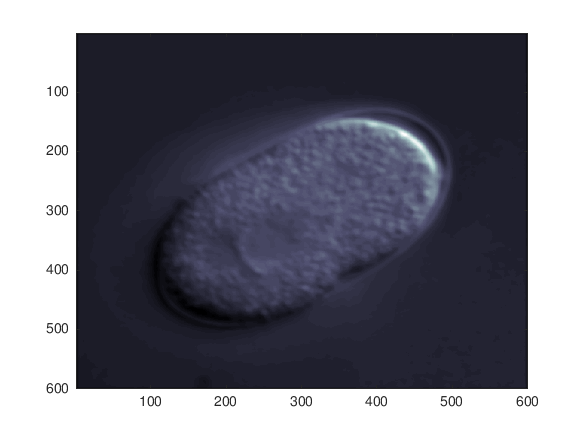

imagesc(res_img(:,:,1))